# Práctica 3: Grafos.

Equipo: Miguel Egido Morales y Alfredo Robledano Abasolo

Grupo: 3ºB

El objetivo de esta práctica es programar el algoritmo de Kruskal mediante un código de tipo function. Para ello subdividiremos el problema en problemas más pequeños. Para ello recuerda que el objetivo es encontrar un subgrafo **CONEXO** $S=(V(G),C)$ del grafo $G=(V(G),E(G))$ tal que $C$ fuera un conjunto conectador. Para ello, la idea es ir añadiendo aristas al grafo $G'=(V(G),\{\})$ hasta conseguir la propiedad de finalización del algoritmo de Kruskal cumpliendo el resto de pasos.

Recordemos que un grafo $G=(V(G),E(G))$ se podía dar por su matriz de adyacencia $A=Ad(G)$.

## **Problema 1:**

Crea un código del tipo function cuyos inputs sean la matriz de adyacencia de un grafo $G$ y un vértice $e=\{i,j\}\in E(G)$ (el cual se puede representar por la entrada $(i,j)=(j,i)$ de la matriz $A$) y sus outputs sean un array de carácteres especificando si dicha arista pertenecía a un ciclo (no trivial) o no. Nótese que si no existe dicha arista debe dar el mensaje de error correspondiente y que si $A=Ad(G)$ no es una matriz correspondiente a una de adyancencia debe dar error también.

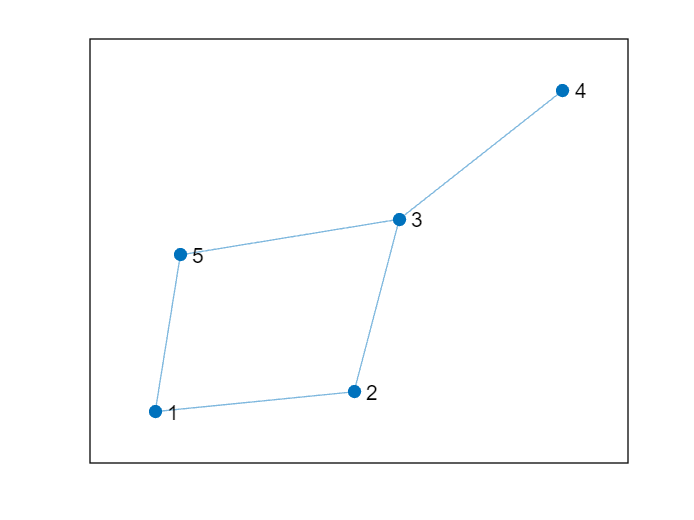

clear, clc, clf

A = [
    0, 1, 0, 0, 1;
    1, 0, 1, 0, 0;
    0, 1, 0, 1, 1;
    0, 0, 1, 0, 0;
    1, 0, 1, 0, 0;
];

G = graph(A);
figure
plot(G)

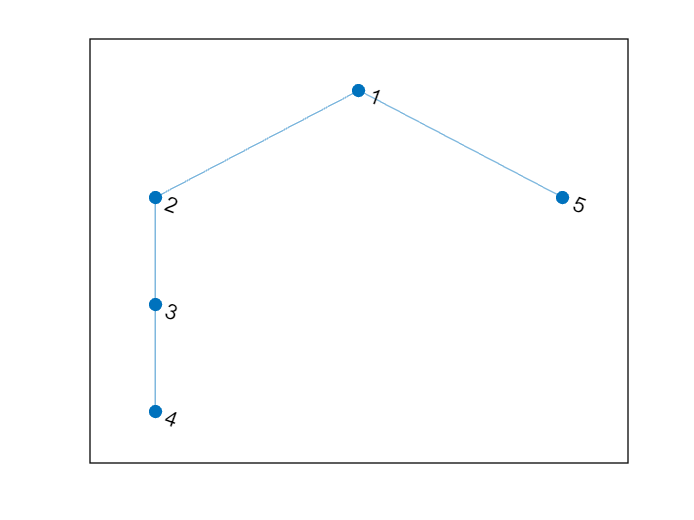

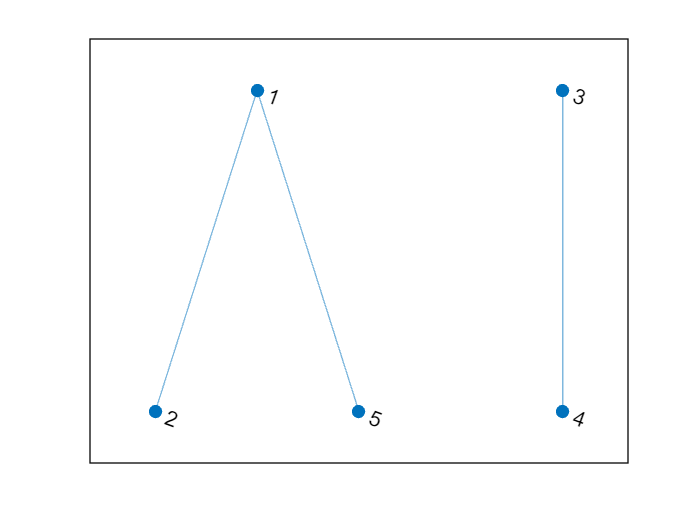

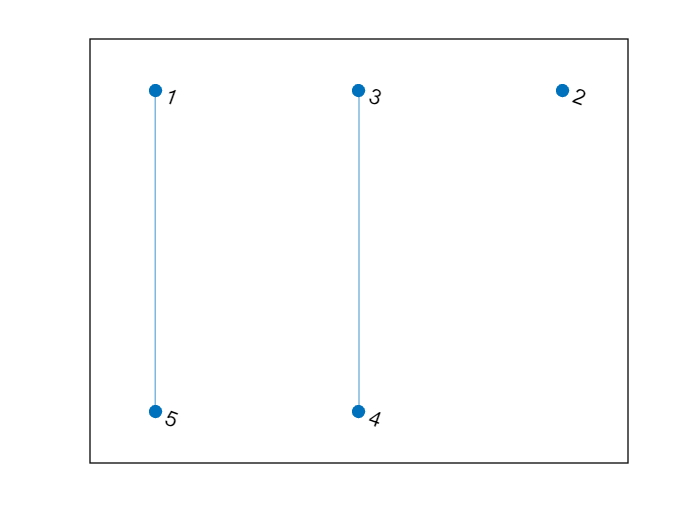


arista = [3, 5];

res = perteneceCiclo(A, arista);


disp(res);

   1



## **Problema 2:**

Crea un código del tipo function cuyos inputs sean la matriz de adyacencia de un grafo $G$ y sus outputs sean un array de carácteres indicando si el grafo es conexo o no.

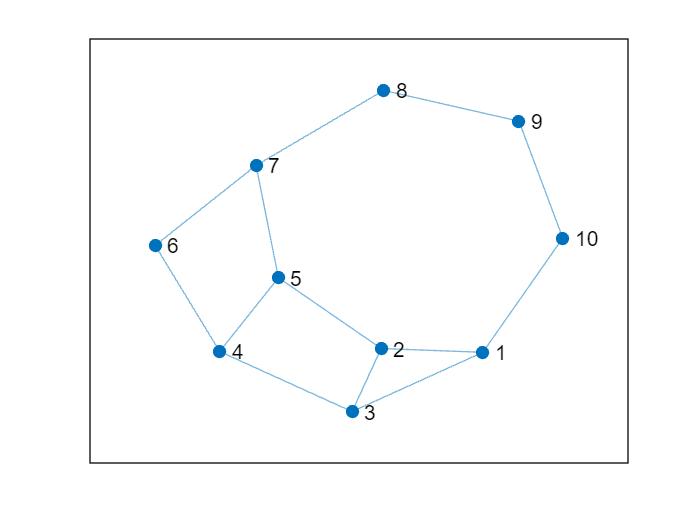

clear, clc, clf
% Ejemplo conexo
A = [
    0 1 1 0 0 0 0 0 0 1;
    1 0 1 0 1 0 0 0 0 0;
    1 1 0 1 0 0 0 0 0 0;
    0 0 1 0 1 1 0 0 0 0;
    0 1 0 1 0 0 1 0 0 0;
    0 0 0 1 0 0 1 0 0 0;
    0 0 0 0 1 1 0 1 0 0;
    0 0 0 0 0 0 1 0 1 0;
    0 0 0 0 0 0 0 1 0 1;
    1 0 0 0 0 0 0 0 1 0;
];


G = graph(A);
figure
plot(G)


resultado = comprobar_conexo(A);
disp(resultado);

El grafo es conexo


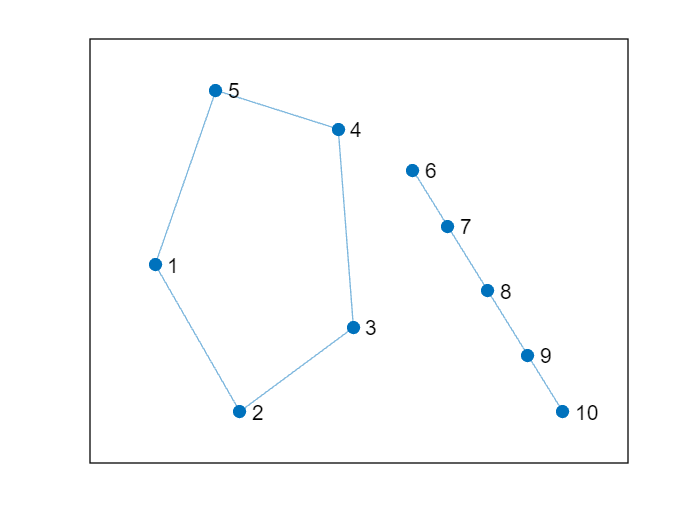


% ejemplo no conexo
B = [
    0 1 0 0 1 0 0 0 0 0;
    1 0 1 0 0 0 0 0 0 0;
    0 1 0 1 0 0 0 0 0 0;
    0 0 1 0 1 0 0 0 0 0;
    1 0 0 1 0 0 0 0 0 0;
    0 0 0 0 0 0 1 0 0 0;
    0 0 0 0 0 1 0 1 0 0;
    0 0 0 0 0 0 1 0 1 0;
    0 0 0 0 0 0 0 1 0 1;
    0 0 0 0 0 0 0 0 1 0;
];



P = graph(B);
figure
plot(P)


res_B = comprobar_conexo(B);
disp(res_B);

El grafo no es conexo


#### Funciones ejercicio 1

function res = perteneceCiclo(A, arista)
    % Dimensiones matriz de adyacencia
    [fil, col] = size(A);

    % Matriz de adyacencia debe ser:
    if ~(fil == col ... % Cuadrada
        && isequal(A, A')) % Simétrica

        disp('Error: Matriz de adyacencia no válida');
        res = false;
        return
    end

    % La arista debe tener:
    if ~(length(arista) == 2 ... % Dos componentes
        && all(arista == round(arista)) ... % Valores enteros
        && arista(1) ~= arista(2) ... % No ciclos propios
        && all(arista >= 1 & arista <= fil)) % Valores entre 1 y nº de aristas

        disp('Error: Arista no válida');
        res = false;
        return
    end
    
    % Se elimina la arista que queremos comprobar
    A(arista, flip(arista)) = 0;
    
    % Se recorrerá el grafo empezando por el nodo determinado por la primera componente de la arista
    vistos = zeros(1, fil);
    vistos(arista(1)) = 1;

    % Si se puede ir de uno de sus extremos al otro tras eliminarla del grafo inicial
    % Entonces la arista pertenece a un ciclo 
    res = dfs(A, arista(1), arista(2), vistos);
end

function pertenece = dfs(grafo, actual, objetivo, visitados)
    % Vecinos al nodo actual
    vecinos = grafo(actual, :);

    % Nos interesan los nodos no visitados
    % Le restamos a los vecinos los que ya hemos visitado
    vecinos_no_visitados = find(vecinos - (vecinos & visitados));
    figure
    plot(graph(grafo))
    
    for i = 1:length(vecinos_no_visitados)
        % Se añade el visitado a los vistos
        visitados(vecinos_no_visitados(i)) = 1;

        % Si el objetivo se encuentra en los vistos terminamos
        if ismember(objetivo, find(visitados))
            pertenece = true;
            break
        end

        % Eliminamos la arista que hemos utilizado para visitar
        arista = [actual, vecinos_no_visitados(i)];
        grafo(arista, flip(arista)) = 0;

        % Por recursión se siguen visitando
        pertenece = dfs(grafo, vecinos_no_visitados(i), objetivo, visitados);
        
        % Permitimos volver hacia atrás en la recursión si pertenece
        if pertenece
            break
        end
    end
end

#### Funciones ejercicio 2

function res = comprobar_conexo(m_ady)
% Esta funcion comprueba si e grafo es conexo o no.
    [fil, col] = size(m_ady);

    if fil ~= col || ~isequal(m_ady, m_ady')
        error('Matriz de adyacencia no válida.');
    end

    if comprobar_coneccion(m_ady)
        res = 'El grafo es conexo';
    else
        res = 'El grafo no es conexo';
    end   

end

function conectividad = comprobar_coneccion(grafo)
    
    v = size(grafo, 1);
    visto = false(1, v);
    cola = 1;
    
    % Se sejecuta mientras siga haya nodos pendientes de explorar en la cola.
    while ~isempty(cola)

        v_actual = cola(1);
        cola = cola(2:end);

        visto(v_actual) = true;
        
        No_visto = find(grafo(v_actual, :) & ~visto);
        
        cola = [cola, No_visto];

    end

    conectividad = all(visto);
end